# Exam July 11, 2018

## Exercise 1

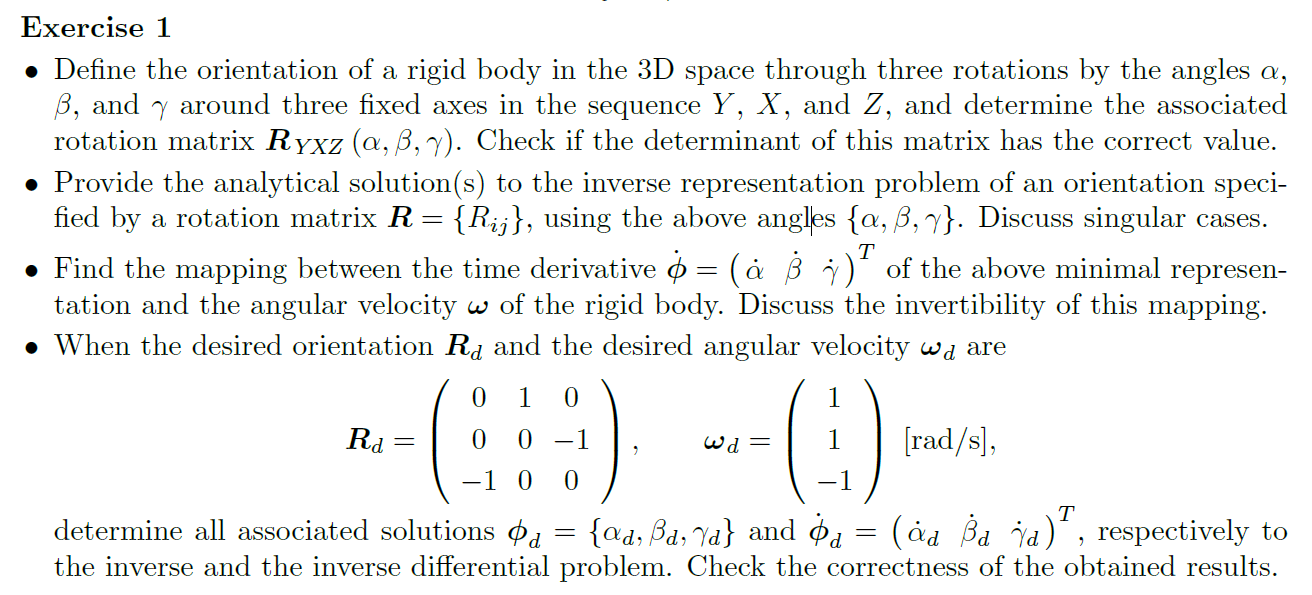

% close all; clear all; clc;
% syms alpha beta gamma
% R=sym('R',[3,3],'real')
% angles = [ beta  alpha gamma]
% 
% [Rx Ry Rz] = getEulerRotationMatrices(angles)
% %To get the rotation matrix after the sequence of rotation YXZ, the product
% %of matrices must be inverted
% Ryxz = Rz*Rx*Ry
% %It can be probed that it is orthonormal with determinant =  1
% determinant = simplify(det(Ryxz))


% Rd = [0 1 0 ; 0 0 -1;-1 0 0 ]
% sol1=solve(Ryxz == Rd)
% solvetoarray(sol1,angles)
% % [a1 b1 g1] = solve(Ryxz == Rd)
% phi = [a1 b1 g1]

## Exercise 2

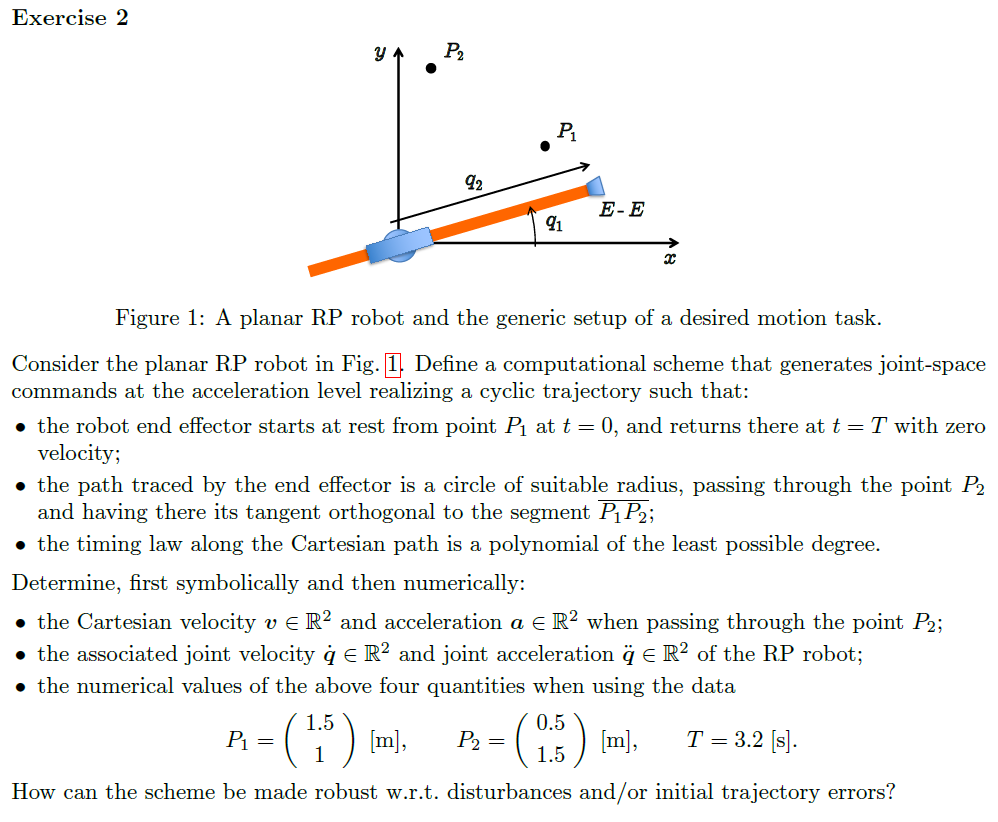

% Initialization of variables
clear
syms phi s t R x0 y0 T t_ 
x0=sym('x0','real')

$$x0 = x_{0}$$

y0=sym('y0','real')

$$y0 = y_{0}$$


x=sym('x',[2,1],'real')

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

y=sym('y',[2,1],'real')

$$y = \left(\begin{array}{c} y_{1}\\ y_{2} \end{array}\right)$$

p = sym('p',[2,1]);

% center point
% p0 = (p(1)+p(2))/2
p0=[x0;y0]%simplify(sum([x,y])'/2)%

$$p0 = \left(\begin{array}{c} x_{0}\\ y_{0} \end{array}\right)$$

p1=[x(1);y(1)]

$$p1 = \left(\begin{array}{c} x_{1}\\ y_{1} \end{array}\right)$$

p2=[x(2);y(2)]

$$p2 = \left(\begin{array}{c} x_{2}\\ y_{2} \end{array}\right)$$

R_=norm(p2-p1)/2%sqrt(sum((p2-p1).^2))%

$$R\_ = \frac{\sqrt{{\left|x_{1}-x_{2}\right|}^{2}+{\left|y_{1}-y_{2}\right|}^{2}}}{2}$$


% Parametric circular path
% p_s = [x0; y0] + R*[cos(s+phi);sin(s+phi)]
p_s = p0 + R*[cos(s+phi);sin(s+phi)]

$$p\_s = \left(\begin{array}{c} x_{0}+R\,\cos\left(\varphi +s\right)\\ y_{0}+R\,\sin\left(\varphi +s\right) \end{array}\right)$$


pd_s = diff(p_s,s)

$$pd\_s = \left(\begin{array}{c} -R\,\sin\left(\varphi +s\right)\\ R\,\cos\left(\varphi +s\right) \end{array}\right)$$

pdd_s = diff(pd_s,s) 

$$pdd\_s = \left(\begin{array}{c} -R\,\cos\left(\varphi +s\right)\\ -R\,\sin\left(\varphi +s\right) \end{array}\right)$$

% initial conditions
% p_s0 =subs(p_s,R,R_)

% p_s0 =subs(p_s0,s,0)

% Cubic polynomial in time
s_t = 2*pi*(3*(t/T)^2 - 2*(t/T)^3)

$$s\_t = 2\,\pi \,\left(\frac{3\,t^{2}}{T^{2}}-\frac{2\,t^{3}}{T^{3}}\right)$$

sd_t = diff(s_t,t)

$$sd\_t = 2\,\pi \,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)$$

sdd_t = diff(sd_t,t)

$$sdd\_t = -2\,\pi \,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$


[spline_fun,Aw_fun,Aa_fun,Ajerk_fun,MaxsVal] = splinesD(2,2,[0 T],[0 2*pi],3,false)

NumJoints = 1

M = 1

v_init = 0

a_init = 0

v_end = 0

a_end = 0

ak = struct with fields:
    ak_1: [1×1 sym]
    ak_2: [1×1 sym]
    ak_3: [1×1 sym]


ans = 1×3 string array
    "0"    "3*q2 - 3*q1"    "2*q1 - 2*q2"


$$spline\_fun = \frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}$$

$$spline\_fun = \frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}$$

$$Aw\_fun = \frac{12\,\pi \,\mathrm{t\_}}{T^{2}}-\frac{12\,\pi \,{\mathrm{t\_}}^{2}}{T^{3}}$$

$$Aa\_fun = \frac{12\,\pi }{T^{2}}-\frac{24\,\pi \,\mathrm{t\_}}{T^{3}}$$

$$Ajerk\_fun = -\frac{24\,\pi }{T^{3}}$$

MaxsVal = struct with fields:
     timepeak: [1×1 struct]
    PeakValue: [1×1 struct]



p_t=subs(p_s,s,spline_fun)

$$p\_t = \left(\begin{array}{c} x_{0}+R\,\cos\left(\varphi +\frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}\right)\\ y_{0}+R\,\sin\left(\varphi +\frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}\right) \end{array}\right)$$

p_d1_t=diff(p_t,t_)

$$p\_d1\_t = \begin{array}{l} \left(\begin{array}{c} R\,\sin\left(\sigma_{1}\right)\,\sigma_{2}\\ -R\,\cos\left(\sigma_{1}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\varphi +\frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}\\ \sigma_{2}=\frac{12\,\pi \,{\mathrm{t\_}}^{2}}{T^{3}}-\frac{12\,\pi \,\mathrm{t\_}}{T^{2}} \end{array}$$

p_d2_t=diff(p_d1_t,t_)

$$p\_d2\_t = \begin{array}{l} \left(\begin{array}{c} -R\,\cos\left(\sigma_{1}\right)\,\sigma_{2}-R\,\sin\left(\sigma_{1}\right)\,\left(\frac{12\,\pi }{T^{2}}-\frac{24\,\pi \,\mathrm{t\_}}{T^{3}}\right)\\ R\,\cos\left(\sigma_{1}\right)\,\left(\frac{12\,\pi }{T^{2}}-\frac{24\,\pi \,\mathrm{t\_}}{T^{3}}\right)-R\,\sin\left(\sigma_{1}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\varphi +\frac{6\,\pi \,{\mathrm{t\_}}^{2}}{T^{2}}-\frac{4\,\pi \,{\mathrm{t\_}}^{3}}{T^{3}}\\ \sigma_{2}={\left(\frac{12\,\pi \,{\mathrm{t\_}}^{2}}{T^{3}}-\frac{12\,\pi \,\mathrm{t\_}}{T^{2}}\right)}^{2} \end{array}$$


% Test. This equals PI, so it means that at the middle of the period, the
% EE will be on the opposite side, which is right!.
%s_t(T/2)

v = pd_s*sd_t

$$v = \left(\begin{array}{c} -2\,\pi \,R\,\sin\left(\varphi +s\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)\\ 2\,\pi \,R\,\cos\left(\varphi +s\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right) \end{array}\right)$$

subs(v,[s,t],[pi,T/2])

$$ans = \left(\begin{array}{c} \frac{3\,\pi \,R\,\sin\left(\varphi \right)}{T}\\ -\frac{3\,\pi \,R\,\cos\left(\varphi \right)}{T} \end{array}\right)$$


a = pd_s*sdd_t + pdd_s*sd_t^2

$$a = \begin{array}{l} \left(\begin{array}{c} 2\,\pi \,R\,\sin\left(\varphi +s\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)-4\,R\,\pi^{2}\,\cos\left(\varphi +s\right)\,\sigma_{1}\\ -4\,R\,\pi^{2}\,\sin\left(\varphi +s\right)\,\sigma_{1}-2\,\pi \,R\,\cos\left(\varphi +s\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)}^{2} \end{array}$$

subs(a,[s,t],[pi,T/2])

$$ans = \left(\begin{array}{c} \frac{9\,R\,\pi^{2}\,\cos\left(\varphi \right)}{T^{2}}\\ \frac{9\,R\,\pi^{2}\,\sin\left(\varphi \right)}{T^{2}} \end{array}\right)$$

Joint space

n =2

n = 2

q = sym('q',[n,1])

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

qd = sym('qd',[n,1])

$$qd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2} \end{array}\right)$$

q_d1 = sym('q%d_d1',[n,1],'real')

$$q\_d1 = \left(\begin{array}{c} q_{1,\mathrm{d1}}\\ q_{2,\mathrm{d1}} \end{array}\right)$$

q_d2 = sym('q%d_d2',[n,1],'real')

$$q\_d2 = \left(\begin{array}{c} q_{1,\mathrm{d2}}\\ q_{2,\mathrm{d2}} \end{array}\right)$$


qdd = sym('qdd',[n,1])

$$qdd = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\\ {\mathrm{qdd}}_{2} \end{array}\right)$$

## dh table

% dhTable = [ pi/2,0, 0, q(1);
%             0,0,q(2),0;
%             ]
% %         links = getDHforTB(dhTable,'alpha');
% links = [
%     Revolute('a', 0, 'alpha', pi/2 ,'d', 0);
% 
%     Prismatic('qlim', [0 10],'alpha',0,'theta',0);
% 
%     ];
% 
% c600 = SerialLink(links);
% c600.teach([0,0],'view','top'  )

% [T_Total T_Partial,R_Total,R_Partial,P_Total, P_Partial] = getTransformationMatrix(dhTable, 'alpha')

 pq = [q(2)*cos(q(1)) ; q(2)*sin(q(1))]

$$pq = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

 Jq=jacobian(pq)

$$Jq = \left(\begin{array}{cc} -q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) \end{array}\right)$$

## solve for q

eq_1q0=pq==p1

$$eq\_1q0 = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)=x_{1}\\ q_{2}\,\sin\left(q_{1}\right)=y_{1} \end{array}\right)$$

solq0=solve(eq_1q0,q)

solq0 = struct with fields:
    q1: [2×1 sym]
    q2: [2×1 sym]


q0_=[atan2(p1(2),p1(1));norm(p1)]

$$q0\_ = \left(\begin{array}{c} \text{atan2}\left(y_{1},x_{1}\right)\\ \sqrt{{\left|x_{1}\right|}^{2}+{\left|y_{1}\right|}^{2}} \end{array}\right)$$

var_ind = 't';
var_dep = 'q';
var_set =[]


var_set =

     []



syms(var_ind)
for i=1:n
   var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
   syms(var_dep_str);
   var_set = [var_set str2sym(var_dep_str)]; % appends the variable to the set
end
syms t t_
qt = var_set.'

$$qt = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

qdt = diff(qt,t)

$$qdt = \left(\begin{array}{c} \frac{\partial }{\partial t}q_{1}\left(t\right)\\ \frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

%pd = 
pqt = [qt(2)*cos(qt(1)) ; qt(2)*sin(qt(1))]

$$pqt = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ \sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) \end{array}\right)$$


pdt_d1=diff(pqt,t);
pdt_d2=diff(pdt_d1,t);

pdt_d2_short=shortdiff(pdt_d2,sym2cell(qt),t,true,2);

temp_dev = 2×1 cell array
    {1×1 sym}
    {1×1 sym}


p_d1_t__halftime=subs(p_d1_t,t_,T/2)% halftime

$$p\_d1\_t\_\_halftime = \left(\begin{array}{c} \frac{3\,\pi \,R\,\sin\left(\varphi \right)}{T}\\ -\frac{3\,\pi \,R\,\cos\left(\varphi \right)}{T} \end{array}\right)$$

p_d2_t_halftime=subs(p_d1_t__halftime,t_,T/2)

$$p\_d2\_t\_halftime = \left(\begin{array}{c} \frac{3\,\pi \,R\,\sin\left(\varphi \right)}{T}\\ -\frac{3\,\pi \,R\,\cos\left(\varphi \right)}{T} \end{array}\right)$$


q_d1_0=simplify(inv(Jq)*p_d2_t_halftime)

$$q\_d1\_0 = \left(\begin{array}{c} -\frac{3\,\pi \,R\,\cos\left(\varphi -q_{1}\right)}{T\,q_{2}}\\ \frac{3\,\pi \,R\,\sin\left(\varphi -q_{1}\right)}{T} \end{array}\right)$$

q_d1_0=simplify(subs(q_d1_0,q,q0_))

$$q\_d1\_0 = \left(\begin{array}{c} -\frac{3\,\pi \,R\,\cos\left(\varphi -\text{atan2}\left(y_{1},x_{1}\right)\right)}{T\,\sqrt{{x_{1}}^{2}+{y_{1}}^{2}}}\\ \frac{3\,\pi \,R\,\sin\left(\varphi -\text{atan2}\left(y_{1},x_{1}\right)\right)}{T} \end{array}\right)$$

q_d1_0=simplify(subs(q_d1_0,R,R_))

$$q\_d1\_0 = \left(\begin{array}{c} -\frac{3\,\pi \,\cos\left(\varphi -\text{atan2}\left(y_{1},x_{1}\right)\right)\,\sqrt{{\left|x_{1}-x_{2}\right|}^{2}+{\left|y_{1}-y_{2}\right|}^{2}}}{2\,T\,\sqrt{{x_{1}}^{2}+{y_{1}}^{2}}}\\ \frac{3\,\pi \,\sin\left(\varphi -\text{atan2}\left(y_{1},x_{1}\right)\right)\,\sqrt{{\left|x_{1}-x_{2}\right|}^{2}+{\left|y_{1}-y_{2}\right|}^{2}}}{2\,T} \end{array}\right)$$


p1_=[1.5,1]';
p2_=[0.5,1.5]';
T_=3.2;
R0_=vpa(subs(R_,[p1;p2],[p1_;p2_]))

$$R0\_ = 0.55901699437494742410229341718282$$

x0_=(p1_+p2_)/2;
phi_=atan2(p1_(2)-p2_(2),p1_(1)-p2_(1))

phi_ = -0.4636

t_0=T_/2

t_0 = 1.6000

p_t_halftime_=vpa(subs(p_t,[phi;R;p0;T;t_],[phi_;R0_;x0_;T_;t_0]))% half time

$$p\_t\_halftime\_ = \left(\begin{array}{c} 0.49999999999999999432530563675958\\ 1.4999999999999999886506112735192 \end{array}\right)$$


p_s_=vpa(subs(p_s,[phi;R;p0],[phi_;R0_;x0_]))%% general path s

$$p\_s\_ = \left(\begin{array}{c} 0.55901699437494742410229341718282\,\cos\left(s-0.46364760900080609351547877849953\right)+1.0\\ 0.55901699437494742410229341718282\,\sin\left(s-0.46364760900080609351547877849953\right)+1.25 \end{array}\right)$$

p_d1_t0_=vpa(subs(p_d1_t__halftime,[phi;R;T],[phi_;R0_;T_]))%t=T/2

$$p\_d1\_t0\_ = \left(\begin{array}{c} -0.73631077818510775683797306247454\\ -1.4726215563702155972427185761531 \end{array}\right)$$

p_d2_t0_=vpa(subs(p_d2_t_halftime,[phi;R;T],[phi_;R0_;T_]))%t=T/2

$$p\_d2\_t0\_ = \left(\begin{array}{c} -0.73631077818510775683797306247454\\ -1.4726215563702155972427185761531 \end{array}\right)$$



%
q_halftime_=[atan2(p_t_halftime_(2),p_t_halftime_(1));norm(p_t_halftime_)]

$$q\_halftime\_ = \left(\begin{array}{c} 1.2490457723982544269648559499292\\ 1.5811388300841896534379753230053 \end{array}\right)$$


q_d1_halftime_=vpa(inv(Jq)*p_d1_t0_)%t=0

$$q\_d1\_halftime\_ = \begin{array}{l} \left(\begin{array}{c} \frac{0.73631077818510775683797306247454\,\sin\left(q_{1}\right)}{\sigma_{1}}-\frac{1.4726215563702155972427185761531\,\cos\left(q_{1}\right)}{\sigma_{1}}\\ -\frac{0.73631077818510775683797306247454\,\cos\left(q_{1}\right)}{{\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}}-\frac{1.4726215563702155972427185761531\,\sin\left(q_{1}\right)}{{\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{2}\,{\cos\left(q_{1}\right)}^{2}+q_{2}\,{\sin\left(q_{1}\right)}^{2} \end{array}$$

q_d1_halftime_=vpa(subs(q_d1_halftime_,q,q_halftime_))%t=0

$$q\_d1\_halftime\_ = \left(\begin{array}{c} 0.14726215563702153699410975088782\\ -1.629893387357172863795219822291 \end{array}\right)$$


pdt_d2_short_=subs(pdt_d2_short,[q,q_d1],[q_halftime_,q_d1_halftime_]);

sol22=solve(p_d2_t0_==pdt_d2_short_)

sol22 = struct with fields:
    q1_d2: [1×1 sym]
    q2_d2: [1×1 sym]


q_d2_halftime_=solvetoarray(sol22,q_d2 )

$$q\_d2\_halftime\_ = \left(\begin{array}{c} 0.45086815039709454037552256244416\\ -1.5956045854027808374508057973655 \end{array}\right)$$